# Decoding context

In the file `DecodingDataRead.m`, we first took the binarized calcium activity and took the sum of events in 2 s bins (60 frames). We then restricted analysis to: 

(1) times when the mouse was running, and 

(2) when the mouse was in context "1" or "2," representing two different cue configurations in the maze. 

Finally, only activity from place cells were used. The resulting pre-processed data was saved for each mouse in a subfolder under the name `binned_activity_decode.mat`.

rootdir = "";
folders = ["M119"+filesep "M120"+filesep "M292"+filesep "M319"+filesep ...
    "M231"+filesep "M314"+filesep "M316"+filesep "M318"+filesep "M210"+filesep];
cohort = ["D1","D1","D1","D1","G1","G1","G1","G1","D1"];
sessions = ["early", "trained", "grouping"];

## Estimate SVM performance for each animal & each condition.

ablate_percent=1;
ablation = 'None';

test_accuracy = nan(length(folders),3);
validation_accuracy = nan(length(folders),3);
s_max = length(sessions);

weights = cell(length(folders),3);
corrs = cell(length(folders),3);

parfor f = 1:length(folders)
    for s = 1:s_max
       try
            A=load(folders(f)+"binned_activity_decode_"+sessions(s)+"_runrest_nopc.mat");
            
            ds = 20; % how many samples to downsample

            N_cells = size(A.a_use,2);
            N_cells_use = round(ablate_percent*N_cells);
            idx_cells_use = [];
            if strcmp(ablation,'random')
                % shuffle the cells
                subset_cells = randperm(N_cells);
                idx_cells_use = subset_cells(1:N_cells_use);
                corrs{f,s} = A.corr_coef(idx_cells_use);

            elseif strcmp(ablation, 'ascend')
                % sort the cells by increasing corr coef (most remap are
                % first)
                [corr_temp,idx_cells_use] = topkrows(A.corr_coef,N_cells_use,'ascend');
                corrs{f,s} = corr_temp;
            
            elseif strcmp(ablation,'descend')
                [corr_temp,idx_cells_use] = topkrows(A.corr_coef,N_cells_use,'descend');
                corrs{f,s} = corr_temp;
            elseif strcmp(ablation,'None')
                idx_cells_use = 1:N_cells_use;
                corrs{f,s} = A.corr_coef(idx_cells_use);
            end

            a_use_sub = A.a_use(1:ds:end,idx_cells_use);            
            context_use_sub = A.context_use(1:ds:end);

            % % reshuffle context
            % shuffle_context_ind = randperm(size(context_use_sub,1));
            % context_use_sub = context_use_sub(shuffle_context_ind);
            
            hpartition = cvpartition(context_use_sub,'Holdout',0.25,'Stratify',true);
            
            X_train = a_use_sub(training(hpartition),:);
            Y_trian = context_use_sub(training(hpartition));
            
            classificationSVM = fitcsvm(...
                X_train, ...
                Y_trian, ...
                'KernelFunction', 'rbf', ...
                'PolynomialOrder', [], ...
                'KernelScale', 'auto', ...
                'BoxConstraint', 1, ... % usuaally 1
                'Standardize', true);
                %'ScoreTransform','sign');
            
            % k-fold partitioning validation
            partitionedModel = crossval(classificationSVM, 'KFold', 20);
            [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
            validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
            
            validation_accuracy(f,s) = validationAccuracy;

            % test set on hold out
            X_test = a_use_sub(test(hpartition),:);
            Y_test = context_use_sub(test(hpartition));
            
            [testPredictions,testScores] = predict(classificationSVM,X_test);
            
            testAccuracy = 1 - loss(classificationSVM,X_test,Y_test);
            
            rocObj_test = rocmetrics(Y_test, testScores,[1,2]);   

            test_accuracy(f,s) = testAccuracy;

            % comparing SVM weights to remapping metric
            weights{f,s} = classificationSVM.Beta;

            display("Completed "+ folders(f)+"binned_activity_decode_"+sessions(s)+".mat")

       catch e
            display("Skipping "+ folders(f)+"binned_activity_decode_"+sessions(s)+".mat")
       end
    end
end

    "Skipping M316\binned_activity_decode_early.mat"

    "Skipping M231\binned_activity_decode_early.mat"

    "Skipping M318\binned_activity_decode_early.mat"

    "Skipping M319\binned_activity_decode_early.mat"

    "Skipping M292\binned_activity_decode_early.mat"

    "Skipping M314\binned_activity_decode_early.mat"

    "Skipping M119\binned_activity_decode_early.mat"

    "Skipping M120\binned_activity_decode_early.mat"

    "Completed M292\binned_activity_decode_trained.mat"

    "Completed M120\binned_activity_decode_trained.mat"

    "Completed M292\binned_activity_decode_grouping.mat"

    "Completed M231\binned_activity_decode_trained.mat"

    "Completed M119\binned_activity_decode_trained.mat"

    "Completed M319\binned_activity_decode_trained.mat"

    "Completed M316\binned_activity_decode_trained.mat"

    "Completed M120\binned_activity_decode_grouping.mat"

    "Completed M119\binned_activity_decode_grouping.mat"

    "Skipping M210\binned_activity_decode_early.mat"

### Stats for Panel B

clear;
datat = readtable("decoder_results_deltas_repeat.xlsx");
WithinSubjectData = table(categorical({'All','PC','NonPC','All','PC','NonPC'})',categorical({'D','D','D','G','G','G'})',VariableNames=["CellSets","Tasks"]);

rm = fitrm(datat,'Score1-Score6 ~ 1','WithinDesign',WithinSubjectData);
ranova(rm,'WithinModel','CellSets+Tasks')

ans = 6×8 table
                              SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            _________    __    __________    ______    __________    __________    __________    __________

    (Intercept)                32.761     1        32.761    2604.5    2.9046e-10    2.9046e-10    2.9046e-10    2.9046e-10
    Error                    0.088049     7      0.012578                                                                  
    (Intercept):CellSets     0.078482     2      0.039241    9.9173     0.0020767      0.012453      0.010844      0.016171
    Error(CellSets)     

rm.multcompare('Tasks','by','CellSets')

ans = 6×8 table
    CellSets    Tasks_1    Tasks_2    Difference     StdErr      pValue       Lower        Upper   
    ________    _______    _______    __________    ________    ________    _________    __________

     All           D          G          0.0198     0.007552    0.034319    0.0019422      0.037657
     All           G          D         -0.0198     0.007552    0.034319    -0.037657    -0.0019422
     NonPC         D          G        0.013382     0.010627     0.24833    -0.011748      0.038511
     NonPC         G          D       -0.013382     0.010627     0.24833    -0.038511      0.011748
     PC            D          G        0.036288     0.011654    0.016991    0.0087306      0.063846
     PC    

rm.multcompare('CellSets','by','Tasks')

ans = 12×8 table
    Tasks    CellSets_1    CellSets_2    Difference     StdErr      pValue        Lower        Upper   
    _____    __________    __________    __________    ________    _________    _________    __________

      D        All           NonPC         0.10182     0.025082     0.011673     0.027956       0.17569
      D        All           PC           0.033052     0.009517     0.024665    0.0050239       0.06108
      D        NonPC         All          -0.10182     0.025082     0.011673     -0.17569     -0.027956
      D        NonPC         PC          -0.068771     0.030997       0.1356     -0.16006      0.022518
      D        PC            All         -0.033052     0.009517     0.024665     -0.06

clear;
datat = readtable("decoder_results_deltas_repeat_ablate.xlsx");
WithinSubjectData = table(...
    categorical({'0UD','0UG','0SD','0SG','25UD','25UG','25SD','25SG','50UD','50UG','50SD','50SG'})', ...
    VariableNames="Spec");

rm = fitrm(datat,'Score1-Score12 ~ 1','WithinDesign',WithinSubjectData);
ranova(rm)

ans = 2×8 table
                         SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        ________    __    __________    ______    __________    __________    __________    _________

    (Intercept):Spec     0.13333    11      0.012121    21.923    2.0059e-19    6.3531e-05    4.2014e-06    0.0022549
    Error(Spec)         0.042571    77    0.00055287                                                                 


rm.multcompare('Spec')

ans = 132×7 table
    Spec_1    Spec_2    Difference     StdErr       pValue        Lower         Upper  
    ______    ______    __________    _________    ________    ___________    _________

     0SD       0SG        0.032042     0.011199     0.31444      -0.018885     0.082969
     0SD       0UD        0.003183     0.001747     0.77262     -0.0047615     0.011128
     0SD       0UG        0.029837     0.010554     0.32584       -0.01816     0.077834
     0SD       25SD       0.020091    0.0050777    0.095031     -0.0030007     0.043183
     0SD       25SG       0.066199     0.014712    0.052627    -0.00070429       0.1331
     0SD       25UD        0.01493    0.0049901       0.274     -0.0077639     0.037623
     0SD       25UG       0.048252     

percents = [zeros(9,1);repmat(25,9,1);repmat(50,9,1)]/100;
cohorts = repmat(datat.Cohort,3,1);
animals = repmat(datat.Animal,3,1);
DU_scores = [datat.Score1;datat.Score5;datat.Score9];
DS_scores = [datat.Score3;datat.Score7;datat.Score11];
GU_scores = [datat.Score2;datat.Score6;datat.Score10];
GS_scores = [datat.Score4;datat.Score8;datat.Score12];

grand_tasks = reordercats(categorical([repmat("DU",27,1);repmat("DS",27,1);repmat("GU",27,1);repmat("GS",27,1)]),["DU","DS","GU","GS"]);
grand_scores = [DU_scores;DS_scores;GU_scores;GS_scores];
grand_percents = repmat(percents,4,1);
grand_animals = repmat(animals,4,1);
grand_cohorts = repmat(cohorts,4,1);

grand_table = table(grand_animals,grand_cohorts,grand_percents,grand_tasks,grand_scores);

grand_glme = fitglme(grand_table,'grand_scores ~ 1 + grand_percents*grand_tasks + (1|grand_animals)')

grand_glme = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             102
    Fixed effects coefficients           8
    Random effects coefficients          9
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    grand_scores ~ 1 + grand_percents*grand_tasks + (1 | grand_animals)

Model fit statistics:
    AIC       BIC        LogLikelihood    Deviance
    -417.7    -391.45    218.85           -437.7  

Fixed effects coefficients (95% CIs):
    Name                                     Estimate     SE          tStat       DF    pValue        Lower        Upper     
    {'(Intercept)'                  }          0.89465    0.024998      35.789    94    1.4748e-56      0.84501       0.94428
    {'grand_percents'           

clear;
datat = readtable("decoder_results_deltas_repeat_ablate.xlsx");
WithinSubjectData = table([0,0,0,0,25,25,25,25,50,50,50,50]',...
    categorical({'D','G','D','G','D','G','D','G','D','G','D','G'})', ...
    categorical({'U','U','S','S','U','U','S','S','U','U','S','S'})', ...
    VariableNames=["Percent","Tasks","Ablation"]);

rm = fitrm(datat,'Score1-Score12 ~ 1','WithinDesign',WithinSubjectData);
ranova(rm,'WithinModel','Percent*Tasks*Ablation')

ans = 16×8 table
                                            SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                          _________    __    __________    ______    __________    __________    __________    __________

    (Intercept)                              67.388    1         67.388    936.27    1.0275e-08    1.0275e-08    1.0275e-08    1.0275e-08
    Error                                   0.50382    7       0.071974                                                                  
    (Intercept):Percent                       38.14    1          38.14    708.64    2.7039e-08    2.7039e-

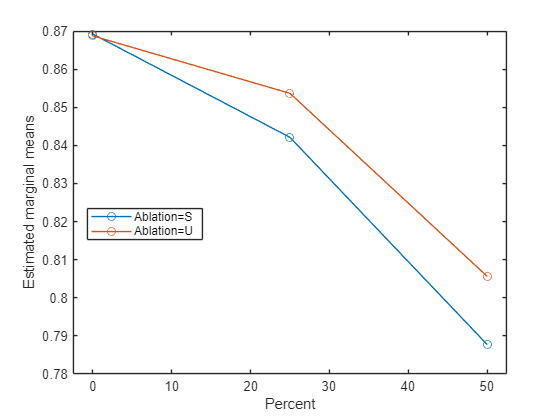

rm.plotprofile('Percent','Group','Ablation')

rm.multcompare('Ablation','by','Tasks')

ans = 4×8 table
    Tasks    Ablation_1    Ablation_2    Difference      StdErr       pValue        Lower        Upper   
    _____    __________    __________    ___________    _________    _________    _________    __________

      D          S             U         -0.00037394    0.0047599      0.93958    -0.011629      0.010882
      D          U             S          0.00037394    0.0047599      0.93958    -0.010882      0.011629
      G          S             U           -0.018937    0.0048418    0.0058143    -0.030386    -0.0074883
      G          U             S            0.018937    0.0048418    0.0058143    0.0074883      0.030386


rm.multcompare('Percent','by','Tasks')

ans = 12×8 table
    Tasks    Percent_1    Percent_2    Difference     StdErr        pValue        Lower        Upper   
    _____    _________    _________    __________    _________    __________    _________    __________

      D          0           25         0.015919     0.0039531      0.012157    0.0042766      0.027561
      D          0           50         0.062958       0.01114     0.0019285      0.03015      0.095767
      D         25            0        -0.015919     0.0039531      0.012157    -0.027561    -0.0042766
      D         25           50          0.04704     0.0083333     0.0019419     0.022498      0.071582
      D         50            0        -0.062958       0.01114     0.0019285    -0.095

rm.multcompare('Ablation','by','Percent')

ans = 6×8 table
    Percent    Ablation_1    Ablation_2    Difference      StdErr       pValue       Lower          Upper   
    _______    __________    __________    ___________    _________    ________    __________    ___________

       0           S             U          0.00048898     0.001768      0.7901    -0.0036916      0.0046696
       0           U             S         -0.00048898     0.001768      0.7901    -0.0046696      0.0036916
      25           S             U           -0.011555     0.004608    0.040546     -0.022451    -0.00065828
      25           U             S            0.011555     0.004608    0.040546    0.00065828       0.022451
      50           S             U           -0.017901   

clear;
datat = readtable("decoder_results_deltas_repeat_ablate.xlsx");
WithinSubjectData = table([25,25,25,25,50,50,50,50]',...
    categorical({'D','G','D','G','D','G','D','G'})', ...
    categorical({'U','U','S','S','U','U','S','S'})', ...
    VariableNames=["Percent","Tasks","Ablation"]);

rm = fitrm(datat,'Score5-Score12 ~ 1','WithinDesign',WithinSubjectData,'WithinModel','Percent*Tasks*Ablation');
ranova(rm,'WithinModel','Percent*Tasks*Ablation')

ans = 16×8 table
                                            SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                          _________    __    __________    ______    __________    __________    __________    __________

    (Intercept)                              43.271    1         43.271       777    1.9642e-08    1.9642e-08    1.9642e-08    1.9642e-08
    Error                                   0.38983    7        0.05569                                                                  
    (Intercept):Percent                       38.14    1          38.14    708.64    2.7039e-08    2.7039e-

mauchly(rm)

ans = 1×4 table
        W         ChiStat    DF      pValue  
    __________    _______    __    __________

    9.7671e-07    61.617     27    0.00016129


epsilon(rm)

ans = 1×4 table
    Uncorrected    GreenhouseGeisser    HuynhFeldt    LowerBound
    ___________    _________________    __________    __________

         1              0.31469          0.46524       0.14286  


rm.multcompare('Ablation','by','Tasks')

ans = 4×8 table
    Tasks    Ablation_1    Ablation_2    Difference     StdErr       pValue       Lower        Upper   
    _____    __________    __________    __________    _________    ________    _________    __________

      D          S             U         -0.0021524    0.0066163     0.75445    -0.017797      0.013493
      D          U             S          0.0021524    0.0066163     0.75445    -0.013493      0.017797
      G          S             U          -0.027303    0.0080747    0.011737    -0.046397    -0.0082097
      G          U             S           0.027303    0.0080747    0.011737    0.0082097      0.046397


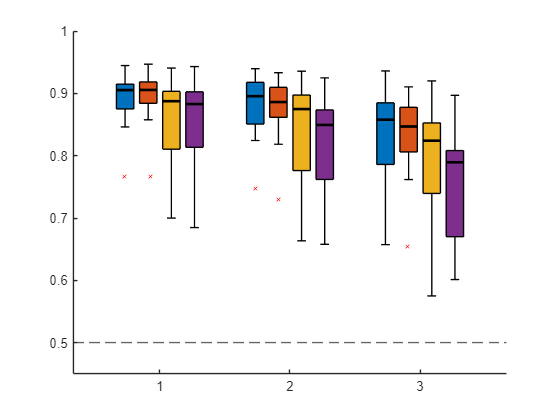

rm.plotprofile('Ablation','Group','Tasks')
ablate_data{1} = [datat.Score1,datat.Score5,datat.Score9];
ablate_data{2} = [datat.Score3,datat.Score7,datat.Score11];
ablate_data{3} = [datat.Score2,datat.Score6,datat.Score10];
ablate_data{4} = [datat.Score4,datat.Score8,datat.Score12];

close all
daboxplot(ablate_data);
ylim([0.45,1])
yline(0.5,'--')

clear;
datat = readtable("decoder_results_runrest.xlsx");

rm = fitrm(datat,'Score1-Score2 ~ 1 + Cohort');
ranova(rm)

ans = 3×8 table
                          SumSq       DF      MeanSq         F         pValue     pValueGG    pValueHF    pValueLB
                        __________    __    __________    ________    ________    ________    ________    ________

    (Intercept):Time     0.0015681    1      0.0015681      5.9085    0.051112    0.051112    0.051112    0.051112
    Cohort:Time         4.4745e-06    1     4.4745e-06    0.016859     0.90093     0.90093     0.90093     0.90093
    Error(Time)          0.0015924    6      0.0002654                                                            


close all
figure()
daboxplot(data_plot)

Unrecognized function or variable 'data_plot'.

ylim([0.45,1])
yline(0.5,'--')

load 'M314\binned_activity_decode_trained_all.mat'

[context_use_long,sort_i_long] = sort(context_use);
A_move_max = movmax(a_use(sort_i_long,:),[1000,1000],1);

disc_i = nansum(A_move_max(context_use_long == 1,:),1)-nansum(A_move_max(context_use_long == 2,:),1);%./nansum(a_use,1);%(nansum(a_use(context_use == 1,:),1)-nansum(a_use(context_use == 2,:),1))./nansum(a_use,1);
disc_i = disc_i./nansum(A_move_max,1);

disc_i(isnan(disc_i)) = 0;
[~,sort_i] = sort(disc_i);

figure()
imagesc((1:size(a_use,1))/60,1:size(a_use,2),a_use(:,sort_i)')
yyaxis right
plot((1:size(a_use,1))/60,context_use,'w')
ylim([0.9,2.1])